 Loading the battery dataset

%% STEP 1: Download and Load Battery Dataset
dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile);
load("singleCellLifeTimeData.mat");

%% STEP 2: Parse and Segment Data
bParser = batteryTestDataParser(data);
bParser.CurrentVariable = 'Current';
bParser.VoltageVariable = 'Voltage';
bParser.TimeVariable = 'DateTime';
bParser.CycleIndexVariable = 'Cycle_Index';
bParser.StepIndexVariable = 'Step_Index';  
segmentedRawDataTable = segmentData(bParser);

%% STEP 3: Extract All Valid "Charge" Data for Cycle 1
chargingData = segmentedRawDataTable(...
    segmentedRawDataTable.Cycle_Index == 1 & ...
    segmentedRawDataTable.CyclingPhases == "Charge" & ...
    segmentedRawDataTable.IsValid, :);
chargingData.TimeInSeconds = seconds(chargingData.DateTime - chargingData.DateTime(1));

Compare power vs. time during each phase and compute total energy delivered during each phase.

% Time relative to start (in seconds)
t = seconds(chargingData.DateTime - chargingData.DateTime(1));
V = chargingData.Voltage;
I = chargingData.Current;

% Calculate Instantaneous Power (Watts)
P = V .* I;

%% STEP 2: Separate CC and CV Regions
vCutoff = 0.995 * max(V); 
transitionIdx = find(V >= vCutoff, 1, 'first');

% Separate vectors
t_cc = t(1:transitionIdx);
P_cc = P(1:transitionIdx);

t_cv = t(transitionIdx:end);
P_cv = P(transitionIdx:end);

%% STEP 3: Compute Total Energy Delivered (Numerical Integration)
% trapz integrates Power (W) over Time (s) to yield Joules (W·s)
E_cc_joules = trapz(t_cc, P_cc); 
E_cv_joules = trapz(t_cv, P_cv); 
E_total_joules = E_cc_joules + E_cv_joules;

% Convert Joules to Watt-hours (1 Wh = 3600 Joules)
E_cc_Wh = E_cc_joules / 3600;
E_cv_Wh = E_cv_joules / 3600;
E_total_Wh = E_total_joules / 3600;

% Percentage shares
pct_cc = (E_cc_joules / E_total_joules) * 100;
pct_cv = (E_cv_joules / E_total_joules) * 100;

%% STEP 4: Display Energy & Power Analysis Results
fprintf('====================================================\n');

fprintf('             POWER & ENERGY ANALYSIS RESULTS        \n');

             POWER & ENERGY ANALYSIS RESULTS        


fprintf('====================================================\n');

fprintf('Peak Power Delivered : %.4f Watts (at t = %.2f s)\n\n', max(P), t(transitionIdx));

Peak Power Delivered : 23.4327 Watts (at t = 1212.15 s)




fprintf('CC Phase Energy      : %.4f Wh (%.2f Joules) [%.1f%% of total]\n', E_cc_Wh, E_cc_joules, pct_cc);

CC Phase Energy      : 3.6787 Wh (13243.29 Joules) [96.6% of total]


fprintf('CV Phase Energy      : %.4f Wh (%.2f Joules) [%.1f%% of total]\n', E_cv_Wh, E_cv_joules, pct_cv);

CV Phase Energy      : 0.1304 Wh (469.60 Joules) [3.4% of total]


fprintf('Total Energy Delivered: %.4f Wh (%.2f Joules)\n', E_total_Wh, E_total_joules);

Total Energy Delivered: 3.8091 Wh (13712.89 Joules)


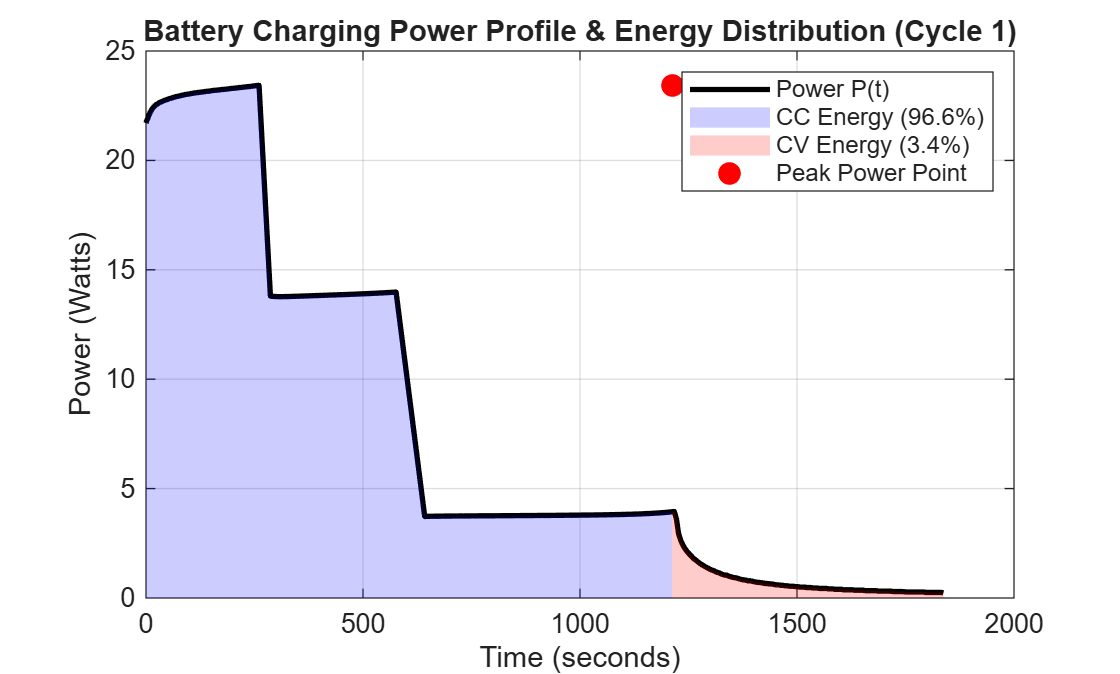


%% STEP 5: Plot Power vs. Time Across Phases
figure('Name', 'Power vs Time Comparison');

% Plot Power profile
plot(t, P, '-k', 'LineWidth', 2, 'DisplayName', 'Power P(t)');
hold on;

% Highlight CC and CV regions
patch([t_cc; flipud(t_cc)], [P_cc; zeros(size(P_cc))], 'b', ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', sprintf('CC Energy (%.1f%%)', pct_cc));

patch([t_cv; flipud(t_cv)], [P_cv; zeros(size(P_cv))], 'r', ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', sprintf('CV Energy (%.1f%%)', pct_cv));

% Mark Peak Power / Transition
plot(t(transitionIdx), max(P), 'or', 'MarkerSize', 8, 'MarkerFaceColor', 'r', ...
    'DisplayName', 'Peak Power Point');

text(t(transitionIdx) + 20, max(P), ...
    sprintf(' Peak Power: %.2f W', max(P)), ...
    'FontSize', 10, 'FontWeight', 'bold');

hold off;

xlabel('Time (seconds)');
ylabel('Power (Watts)');
title('Battery Charging Power Profile & Energy Distribution (Cycle 1)');
grid on;
legend('Location', 'northeast');